clc
clear
file_num = 1;
root_dir = "C:\Users\olive\OneDrive - University of Surrey\individual project\data\raw_data";
testdate = "";
freq = 1/333;

folder = root_dir + "/imu_noise.csv";

files = dir(folder);
display(files)

files = struct with fields:
       name: 'imu_noise.csv'
     folder: 'C:\Users\olive\OneDrive - University of Surrey\individual project\data\raw_data'
       date: '12-May-2022 20:43:24'
      bytes: 70957
      isdir: 0
    datenum: 7.3865e+05



file_name = files(file_num).folder + "/" + files(file_num).name;
% file = importdata(file_name,',');
% uav_data = file.data(file.data(:,1) < 2000000, :);

opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["time", "gx", "gy", "gz", "ax", "ay", "az", "ign"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
uav_data = readtable(file_name, opts);

uav_data = uav_data(uav_data.time>560000, :);
uav_data = uav_data(uav_data.time<1800000, :);

%interpolate
rebase_time = @(x,f) freq:freq:1/f*length(x);
rebase_uav = @(x) interp1((uav_data{:,1}-560000)./1e6, x, rebase_time(x,333));
uav_data_interp = [];
for col = 2:7
    temp = rebase_uav(uav_data{:,col});
    uav_data_interp(:, col-1) = temp(1:end-1);
end

clf
axis = 2;
start = 1;
rms(uav_data_interp(start:end,axis))

ans = 0.0124

mean(uav_data_interp(start:end,axis))

ans = -0.0123

std(uav_data_interp(start:end,axis))

ans = 0.0013

min(uav_data_interp(start:end,axis))

ans = -0.0147

max(uav_data_interp(start:end,axis))

ans = -0.0079

length(uav_data_interp(start:end,axis))

ans = 412


mean(uav_data_interp(start:end,axis)) - min(uav_data_interp(start:end,axis))

ans = 0.0024

max(uav_data_interp(start:end,axis)) - mean(uav_data_interp(start:end,axis))

ans = 0.0044

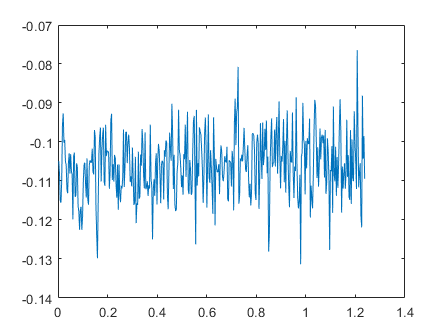

plot(rebase_time(uav_data_interp(start:end,axis), 333),uav_data_interp(start:end,axis))

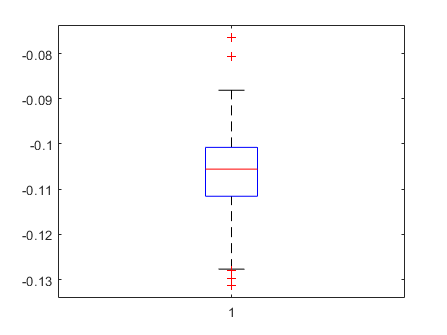

boxplot(uav_data_interp(start:end,axis))

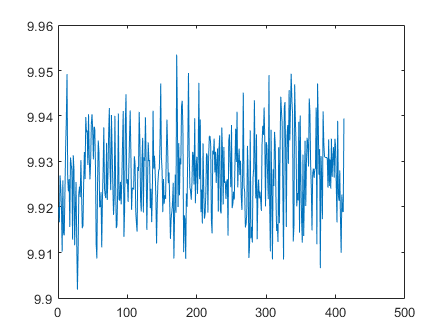

a = vecnorm([uav_data_interp(:,4), uav_data_interp(:,5), uav_data_interp(:,6)]');
plot(a)